# problem 3

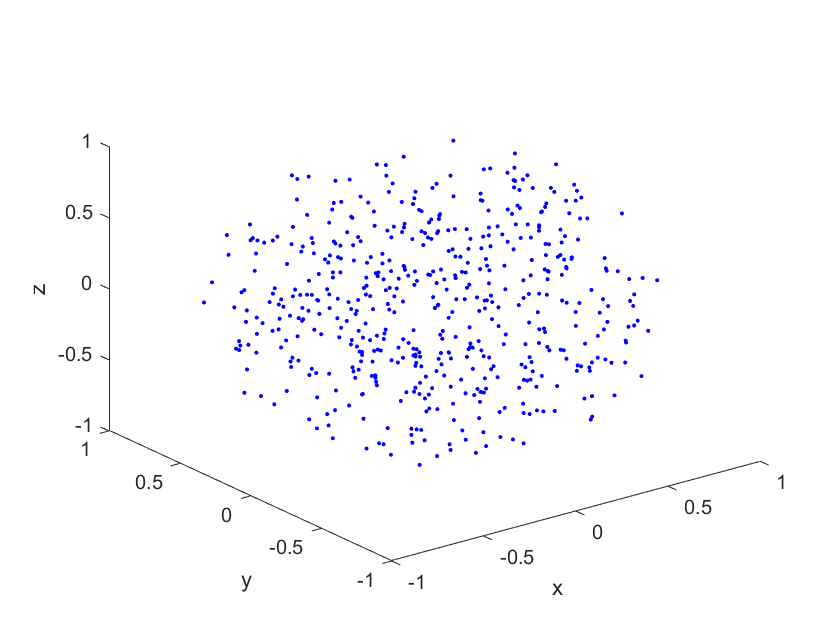

 tic
        nI=1000;
         Sx=-1+2*rand(nI,1);
         Sy=-1+2*rand(nI,1);
         Sz=-1+2*rand(nI,1);
         sx=zeros(1);
         sy=zeros(1);
         sz=zeros(1);

         d=0;
         for l=1:numel(Sx)
                 sigma=sqrt(Sx(l)^2+Sy(l)^2+Sz(l)^2);
             if sigma<=1
                 d=d+1;
                 sx(d)=Sx(l);
                 sy(d)=Sy(l);
                 sz(d)=Sz(l);
             end
         end
         plot3(sx,sy,sz,'b.')
         
xlabel('x')
ylabel('y')
zlabel('z')

  toc

Elapsed time is 0.315326 seconds.


## b

in this code, to improve efficiency, the random sets generated is stored in matrix in the form such that each row represents a component.

Data generated from each dimensions are stored in cell.

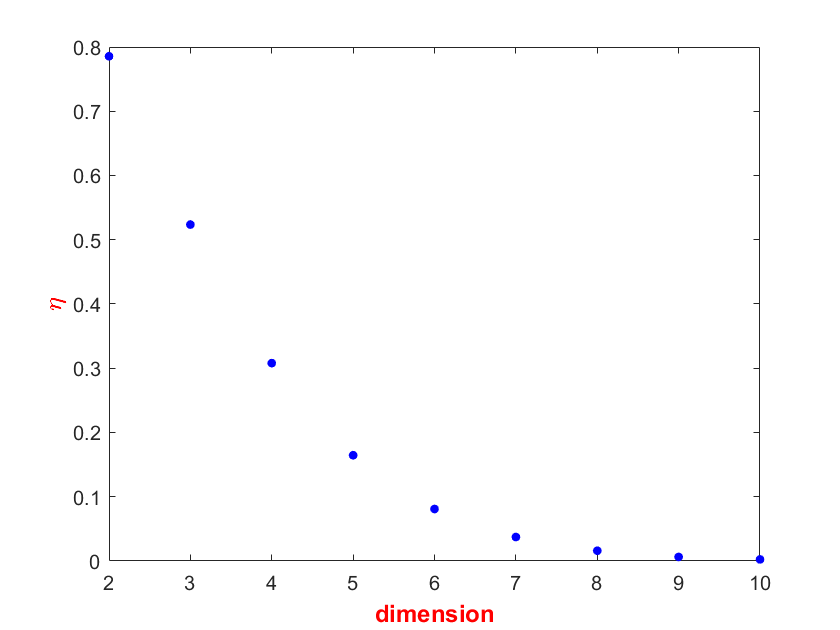

tic
nI=1000000; ndim=2:10; 
r=1;
KK = {1,length(ndim)};
nn = 1;
xmat=zeros(1,nI);
psi_nD=zeros(1,length(ndim));
for l=1:length(ndim)
    for i=1:ndim(l)
    xmat(i,:) = -1+2*rand(1,nI); % store rand vecs in matrix
    end
    d=0;
    Rnd_nD=zeros(ndim(l),ndim(l));
    for k=1:nI
    sigma=0;
        for j=1:ndim(l)
            sigma=sigma+ xmat(j,k)^2;
        end
        if sqrt(sigma)<=r
            d=d+1;
            Rnd_nD(:,d)=xmat(:,k);
            
        end 
        
    end
   psi_nD(l)=length(Rnd_nD)/nI;
   KK{nn} = {Rnd_nD};
   nn = nn+1;
end
figure(2)
plot(ndim,psi_nD,'b.',"MarkerSize",15)

xlabel('dimension','FontSize',12,'FontWeight','bold','Color','r')
ylabel('\eta','FontSize',12,'FontWeight','bold','Color','r')

toc

Elapsed time is 6.924477 seconds.


from the graph we can say the that  $\eta = \frac{\# pts}{total \# pts}$  is inversly proportional to the dimension, thus the higher the dimension the the more spread out the data set and the small number of points captured and vise versa.

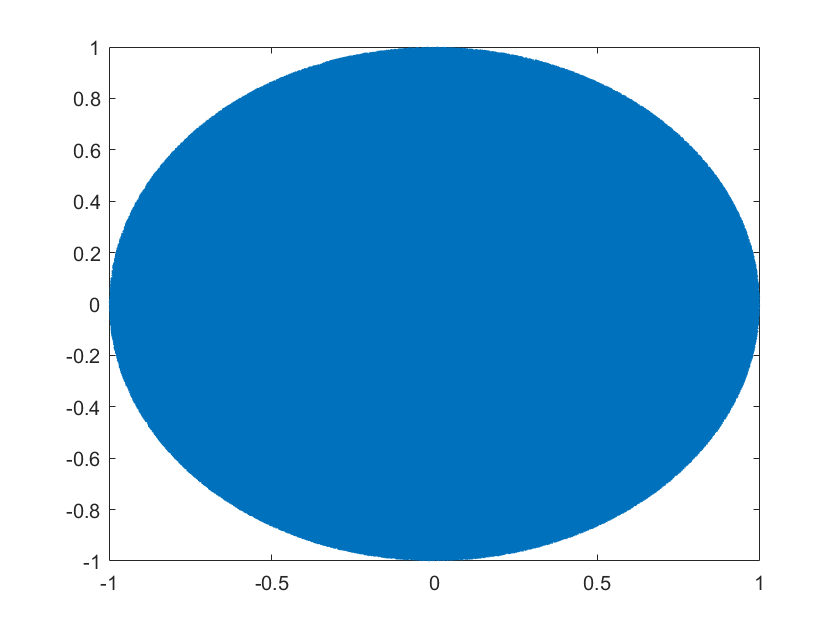

AA=KK{1,1};
AA=cell2mat(AA);
plot(AA(1,:),AA(2,:))

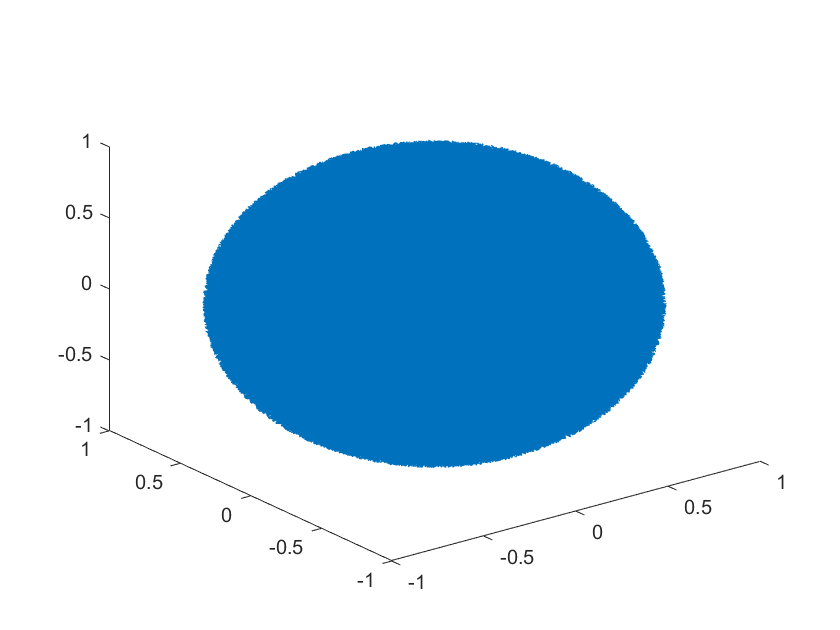

BB=KK{1,2};
BB=cell2mat(BB);
plot3(BB(1,:),BB(2,:),BB(3,:))

## 3c

nd=10;
psi_nd=zeros(nd,1);

psi_nd =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


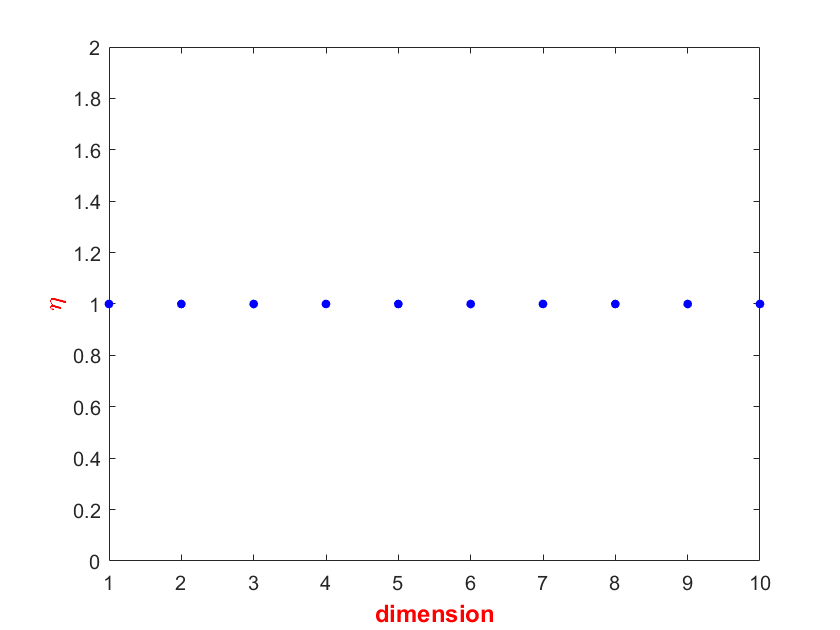

for ndim=1:nd
        pts=0;
        t_pts=0;
        %matrix to store vectors
        xmat=zeros(nI,ndim);
        while pts < nI
            t_pts=t_pts+1;
            x=zeros(ndim,1);
            for i=1:ndim
               x(i)=randn();
            end
            sq_x=sum(x.^2);
            g=rand()^(1/ndim);
            x=g.*(x/sqrt(sq_x));
            pts=pts+1;
            xmat(m,:)=x;
        end
         psi_nd(ndim)=pts/t_pts;
end
     figure(5)
plot(1:nd,psi_nd','b.',"MarkerSize",15)

xlabel('dimension','FontSize',12,'FontWeight','bold','Color','r')
ylabel('\eta','FontSize',12,'FontWeight','bold','Color','r')